clc; clear all; close all;

m = 80; % kg
b1 = 15; % Drag coefficient before parachute is deployed
b2 = 7*b1; % Drag coefficient after parachute is deployed
g = -9.81; % Gravity, m/s^2

#### Differential Equation


$$\begin{array}{l}
F=\mathrm{ma}\\
F=m\;\frac{\mathrm{dv}}{\mathrm{dt}}\\
F=\mathrm{mg}-v\cdot b\\
m\;\frac{\mathrm{dv}}{\mathrm{dt}}=\mathrm{mg}-\mathrm{vb}\\
\frac{\mathrm{dv}}{\mathrm{dt}}=g-\frac{v\cdot b}{m}\\
\frac{\mathrm{dv}}{\mathrm{dt}}=\frac{b}{m}\left(g\cdot \frac{m}{b}-v\right)\\
\frac{\mathrm{dv}}{\mathrm{dt}}=\frac{b}{m}\left(g\cdot \frac{m}{b}-v\right)\\
\frac{\mathrm{dv}}{\mathrm{dt}}=-\frac{b}{m}\left(v-g\cdot \frac{m}{b}\right)\\
\frac{\mathrm{dv}}{\left(v-g\cdot \frac{m}{b}\right)}=-\frac{b}{m}\mathrm{dt}\\
\int \frac{1}{\left(v-g\cdot \frac{m}{b}\right)}\mathrm{dv}=-\frac{b}{m}\int \;\mathrm{dt}\\
\ln \left(v-g\cdot \frac{m}{b}\right)=-\frac{b}{m}\cdot t+C_1 \\
e^{\ln \left(v-g\cdot \frac{m}{b}\right)} =e^{\left(-\frac{b}{m}\cdot t+C_1 \right)} \\
v-g\cdot \frac{m}{b}=C_1 e^{\left(-\frac{b}{m}\cdot t\right)} \\
v=C_1 \cdot e^{\left(-\frac{b}{m}\cdot t\right)} +g\cdot \frac{m}{b}\;\;\;\;\;\;\;\;\;\;\;\;,\;\;\;\mathrm{General}\;\mathrm{solution}\\
v\left(0\right)=0\\
0=C_1 \cdot e^0 +g\cdot \frac{m}{b}\\
C_1 =-g\cdot \frac{m}{b}
\end{array}$$


C_1 = -g*m/b1

C_1 =                      52.32


#### Velocity Equation from t=0 to t=50


$$v=-g\cdot \frac{m}{b_1 }\cdot e^{\left(-\frac{b_1 }{m}\cdot t\right)} +g\cdot \frac{m}{b_1 }\;\;\;\;\;\;,\;\;\;\;\;\;0\le t\le 50$$


Then using the equation above to find an expression for y:


$$\begin{array}{l}
v=\frac{\mathrm{dy}}{\mathrm{dt}}\\
\frac{\mathrm{dy}}{\mathrm{dt}}=-g\cdot \frac{m}{b_1 }\cdot e^{\left(-\frac{b_1 }{m}\cdot t\right)} +g\cdot \frac{m}{b_1 }\\
\int \mathrm{dy}=-g\cdot \frac{m}{b_1 }\int e^{\left(-\frac{b_1 }{m}\cdot t\right)} \mathrm{dt}+g\cdot \frac{m}{b_1 }\int \mathrm{dt}\\
y=-g\cdot \frac{m}{b_1 }\int e^u \;\mathrm{dt}+g\cdot \frac{m}{b_1 }\int \mathrm{dt}\\
y=-g\cdot \frac{m}{b_1 }\int e^u \left(-\frac{m}{b_1 }\right)\mathrm{du}+g\cdot \frac{m}{b_1 }t\\
u=-\frac{b_1 }{m}\cdot t\\
\frac{\mathrm{du}}{\mathrm{dt}}=-\frac{b_1 }{m}\\
\mathrm{dt}=\frac{m}{-b_1 }\mathrm{du}\\
y=g\cdot \frac{m^2 }{{b^2 }_1 }\cdot e^{\left(-\frac{b_1 }{m}\cdot t\right)} +g\cdot \frac{m}{b_1 }\cdot t+A\\
y\left(0\right)=0\\
0=g\cdot \frac{m^2 }{{b^2 }_1 }\cdot e^{\left(0\right)} +g\cdot \frac{m}{b_1 }\cdot 0+A\\
A=-g\cdot \frac{m^2 }{{b^2 }_1 }
\end{array}$$


A = -g*m^2/b1^2

A =                     279.04


#### Position Equation from t=0 to t=50


$$y=g\cdot \frac{m^2 }{{b^2 }_1 }\cdot e^{\left(-\frac{b_1 }{m}\cdot t\right)} +g\cdot \frac{m}{b_1 }\cdot t-g\cdot \frac{m^2 }{{b^2 }_1 }$$

$$\;\;\;\;\;\;,\;\;\;\;\;\;0\le t\le 50$$



$$y\left(50\right)=g\cdot \frac{m^2 }{{b^2 }_1 }\cdot e^{\left(-\frac{b_1 }{m}\cdot 50\right)} +g\cdot \frac{m}{b_1 }\cdot 50-g\cdot \frac{m^2 }{{b^2 }_1 }$$


y_50 = g*m^2/b1^2*exp(-b1/m*50)+g*m/b1*50+A+4000

y_50 =           1663.01633231964



$$v\left(50\right)=-g\cdot \frac{m}{b_1 }\cdot e^{\left(-\frac{b_1 }{m}\cdot 50\right)} +g\cdot \frac{m}{b_1 }\;$$


v_50 = -g*m/b1*exp(-b1/m*50)+C_1

v_50 =           52.3244376900681


#### After parachute is deployed

$v$ after 50s:


$$v=C_2 \cdot e^{\left(-\frac{b}{m}\cdot t\right)} +g\cdot \frac{m}{b}\;\;\;\;\;\;\;\;\;\;\;\;,\;\;\;\textrm{General}\;\textrm{solution}$$



$$v\left(0\right)=-52\ldotp 315\frac{m}{s}$$



$$\begin{array}{l}
-52=C_2 \cdot e^{\left(-\frac{b_2 }{m}\cdot 0\right)} +g\cdot \frac{m}{b_2 }\\
-52=C_2 \cdot e^0 +g\cdot \frac{m}{b_2 }\\
C_2 =-52-g\cdot \frac{m}{b_2 }=-44\ldotp 53
\end{array}$$


C_2 = -v_50-g*m/b2

C_2 =          -44.8501519757824



$$\begin{array}{l}
v=-44\ldotp 85\cdot e^{\left(-\frac{b_2 }{m}\cdot t\right)} +g\cdot \frac{m}{b_2 }\;\;\;\;\;\;,\;\textrm{Velocity}\;\textrm{after}\;50s\\
y=\int v=-44\ldotp 85\int e^{\left(-\frac{b_2 }{m}\cdot t\right)} \textrm{dt}+g\cdot \frac{m}{b_2 }\int \textrm{dt}\\
y=\int v=-44\ldotp 85\int e^u \frac{m}{-b_2 }\textrm{du}+g\cdot \frac{m}{b_2 }\int \textrm{dt}\\
u=-\frac{b_2 }{m}\cdot t\\
\frac{\textrm{du}}{\textrm{dt}}=-\frac{b_2 }{m}\\
\textrm{du}=-\frac{b_2 }{m}\textrm{dt}\\
\textrm{dt}=\frac{m}{-b_2 }\textrm{du}\\
y=-44\ldotp 85\cdot \frac{m}{-b_2 }\cdot e^{\left(-\frac{m}{b_2 }\cdot t\right)} +g\cdot \frac{m}{b_2 }\cdot t+C_3 \\
y\left(0\right)=0\\
y=-44\ldotp 85\cdot \frac{m}{-b_2 }\cdot e^0 +g\cdot \frac{m}{b_2 }\cdot 0+C_3 \\
0=-44\ldotp 85\cdot \frac{m}{-b_2 }+C_3 \\
C_3 =-33\ldotp 93
\end{array}$$


C_3 = C_2*m/b2

C_3 =          -34.1715443625009


## Piecewise plotting

t1 = 0;
t2 = 0;
idx1 = 1;
idx2 = 1;
dt = 10^-4

dt =                     0.0001



y = 0;
y2 = 0;

while t1 <=50.001
y = g * m^2/b1^2 * exp(-(b1/m)*t1) + g * (m/b1)*t1 - g * (m^2/b1^2) + 4000;
t_plot_1(idx1) = t1 ;
y_plot_1 (idx1) = y;
t1 = t1 + dt;
idx1 = idx1 + 1;
end

while y2 >= -y
y2 = C_2*m/-b2*exp(-m/b2*t2)+g*m/b2*t2+C_3;
t_plot_2(idx2) = t2;
y_plot_2(idx2) = y2;

t2 = t2 + dt;
idx2 = idx2 + 1;
end

plot (t_plot_1 ,y_plot_1 , 'r', 'LineWidth', 2)
hold on
plot (t_plot_2+50 ,1664+y_plot_2 , 'k', 'LineWidth', 2)
grid on
legend("Free fall", "Parachute deployed", 'interpreter','latex')
title("Skydive plot", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
t_int_1 = t_plot_1(end)

t_int_1 =           50.0009000005363


t_int_2 = t_plot_2(end)

t_int_2 =           217.920200006111


total_skydive = t_int_1 + t_int_2

total_skydive =           267.921100006647


## Numerical approach

simTime = 300; % s
t = 0; % Start time
idx = 1; % Index for logging

% I.C
y = 4000; % y(0) = 4000 m
yDot = 0; % y'(0) = 0 m/s

% Calculation
while t < simTime

    % Set the drag coefficient based on if the parachute has been deployed
    if t <= 50
        b = b1;
    else
        b = b2;
    end

    % Calculate forces
    F_g = m*g; % Force caused by gravity = mass * gravity (acceleration)
    F_c = yDot*b; % Force caused by drag/wind resistance = velocity * drag coefficient

    % Newton's second law: F = ma
    %                      a = F/m
    yDotDot = (F_g-F_c)/m;

    % Save results for plotting
    timePlot(idx) = t;
    yPlot(idx) = y;
    yDotPlot(idx) = yDot;
    yDotDotPlot(idx) = yDotDot;

    % Time integrate y, yDot and update time, index variables
    y = y+yDot*dt;          % Position
    yDot = yDot+yDotDot*dt; % Velocity
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

x = timePlot(yPlot>=0);
total_skydive_numerical = x(end)

total_skydive_numerical =           267.927300004381



difference_between_methods = total_skydive_numerical-total_skydive

difference_between_methods =        0.00619999773374502


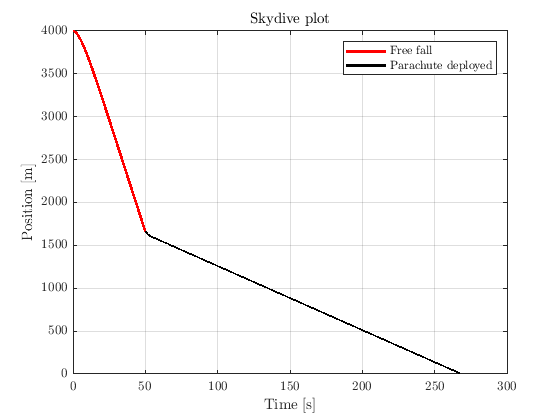


hold off

plot(timePlot(yPlot >= 0), yPlot(yPlot >= 0), 'b','LineWidth',2)
grid on
legend("Numerical calculation", 'interpreter','latex')
title("Numerical approach", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')

## Analytical vs. numerical approach

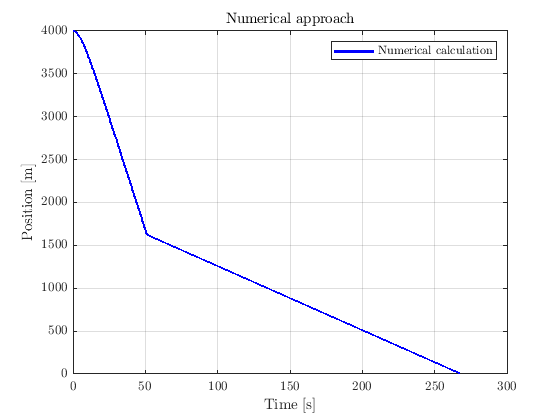

% Plotting
hold off

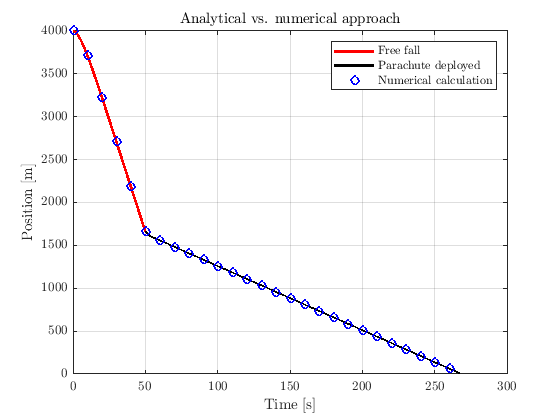

plot (t_plot_1 ,y_plot_1 , 'r', 'LineWidth', 2)
hold on
plot (t_plot_2+50 ,1664+y_plot_2 , 'k', 'MarkerIndices', 1:100000:length(y_plot_2), 'LineWidth', 2)
plot(timePlot(yPlot >= 0), yPlot(yPlot >= 0), 'bo', 'MarkerIndices', 1:100000:length(yPlot),'LineWidth',2)
grid on
legend("Free fall", "Parachute deployed", "Numerical calculation", 'interpreter','latex')
title("Analytical vs. numerical approach", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')